# CISC271, 2024, Week 11, Day 1: Kernel PCA

% Load the Iris data

load fisheriris
x = zscore(meas);
y = zeros(size(species, 1), 1);
y(~strcmp(species, 'setosa')) = 1;

%Zero-mean the data
M = meas - ones(size(meas,1),1)*mean(meas);


## Conventional PCA

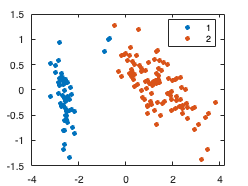

%SVD of the zero-mean data
[~,~,VConv] = svd(M); %VConv is 4x4

%Calculate the scores
zConv = M*VConv(:,1:2);

%Perform k-means clustering on the reduced data
[clustersConv] = kmeans(zConv, 2);
gscatter(zConv(:,1), zConv(:,2), clustersConv)

## Kernel PCA With Gaussian Kernel

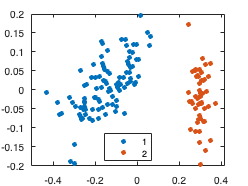

%With kernel PCA we will be calculating the observation-based scatter
%matrix (Su) while working with the standardized data.

[numObs, ~] = size(x);

% Anonymous function: centering matrix of parameterized size (given to you
% in A5)
Gmat =@(k) eye(k) - 1/k*ones(k,k);

% We need to choose an appropriate sigma for our gaussian distribution
sigma = 2*numObs;

% Calculate gram matrix
    % To calculate the gram matrix W:
        % Calculate the distance between every pair of observations using
        % equation 33.14 (hint: you can do this using for loops or it can be done
        % in 2 lines of MATLAB with an anonymous function and built-in MATLAB pdist2)
W = gramgauss(x, sigma); %150 x 150 (relationship of data when projected into higher dimensional space)

% Calculate the kernel observation-style scatter matrix
Su = Gmat(numObs)*W*Gmat(numObs); %(Eq. 33.12) 150x150

% Calculate the singular values of Su
[SuEigVecs, SuEigVals] = eig(Su, 'vector');

%Order Eigenvectors such that vector associated with largest value is first
[SuEigVals, ndx] = sort(SuEigVals, 'descend');
SuEigVecs = SuEigVecs(:, ndx);

%Find the scores for kernel PCA with Gram matrix
zGram = Su*SuEigVecs(:, 1:2); % (150x150)*(150x2) = (150x2)

[clustersGram] = kmeans(zGram, 2);
gscatter(zGram(:,1), zGram(:,2), clustersGram)



%% NOTE: Your methods section description for kernel PCA in A5
% will be heavily weighted (I am giving you a large chunk of the
% code so you need to show me you understand the mathemetical
% algorithm). Focus on why we can substitute these matrices
% compared to normal PCA. Class notes 33 is a great resource
% for this. Make sure you are describing the algorithm in your
% own words; do not simply paraphrase the class notes.
